# -ESERCIZIO 3

 **Sia dato il seguente segnale periodico ***x = sin(2*pi*t + pi/6) + cos(2*pit*8*t + pi/3) ***scrivere uno script di MATLAB che, dopo opportuna scelta del passo di campionamento e dell'intervallo di osservazione, mostri le ampiezze e le fasi del segnale mediante l'algoritmo DFT.**

close all
clc
clear


IL SEGNALE CONTINUO

tenendo conto della forma generale x(tn) = A*sin(2*pi*f*tn + phi) le ampiezze delle rispettive armoniche

A1 = 1; 
A2 = 1;


le frequenze delle rispettive armoniche

f1 = 1;
f2 = 8;


le fasi delle rispettive armoniche

phi1 = pi/6;
phi2 = pi/3;


scelgo la frequenza di campionamento in Hz pari a

fc = 256; %1000

La frequenza di campionamento deve essere maggiore o uguale al doppio della frequenza massima contenuta nel segnale (Teorema di Shannon), cioè fc >= 2*fmax. Il mancato rispetto di questo teorema si incorre nel fenomeno noto come aliasing, cioè le componenti di suono a frequenza più elevate saranno sottocampionate e appariranno a frequenze più basse. All’aumentare della frequenza di campionamento, crescerà il numero di  valori nell’unità di tempo; di conseguenza l’errore che commetterò sarà  minore.

 Pertanto, posso calcolare il periodo di campionamento tramite la seguente relazione:

Tc = 1/fc;

posso notare che essendo Tc = 0.0039, esso soddisfa il teorema del campionamento secondo il quale Tc < T/2 (osservando che il periodo del segnale in questione è pari a 1). Pertanto, questo significa che la condizione necessaria (w < wc/2 dove w è la banda del segnale continuo x(t)) è soddisfatta.

scelgo un numero di campioni pari a

N = 256;

implemento il dominio temporale nella seguente maniera

tn = [0: Tc :(N-1)*Tc];

potevo anche definirlo come tn = [0:Tc:(1/f-Tc)]; tale che N=length(tn);

il segnale sarà

x = A1*sin(2*pi*f1*tn + phi1) + A2*cos(2*pi*f2*tn + phi2);

rappresento il segnale continuo

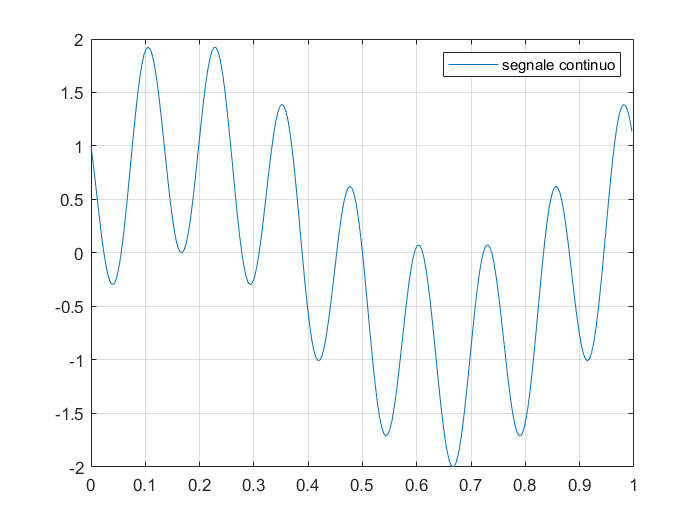

figure(1);
plot( tn, x );
legend('segnale continuo');
grid;

 IL SEGNALE CAMPIONATO

per campionamento di un segnale s'intende la scelta di un intervallo di tempo Tc (periodo di campionamento) e il successivo prelevamento dei valori del segnale in istanti multipli di Tc. Ovviamente, dal periodo di campionamento si ottiene una frequenza di campionamento fc = 1/Tc, cioè sottoponendo un segnale x a campionamento con periodo di campionamento Tc significa che estrapoleremo da x ben fc valori/secondo.

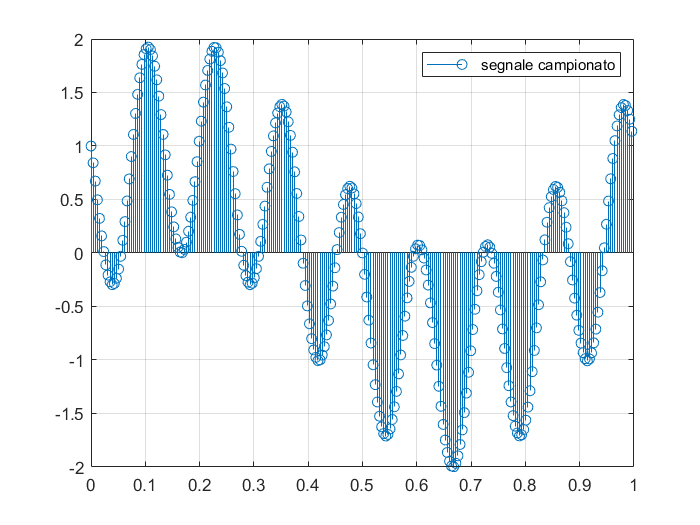

figure(2);
stem( tn, x );
legend('segnale campionato');
grid;

SPETTRO

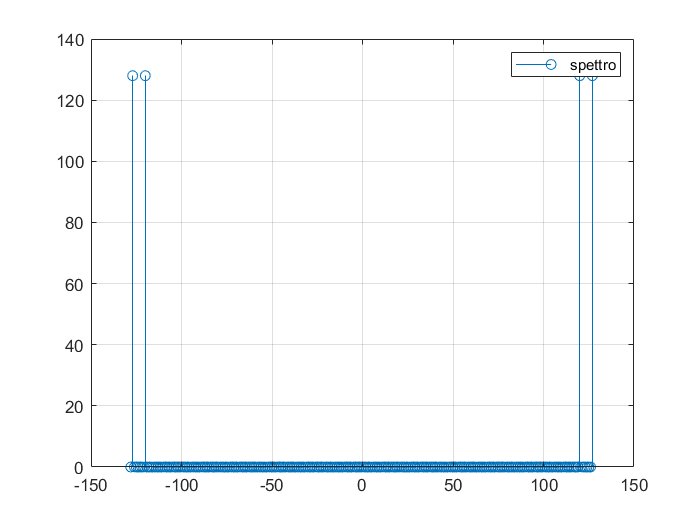

X = fft(x); 

wc = 2*pi/Tc;

fc = 1/Tc;

wk = [-fc/2: fc/N :fc/2-fc/N];

figure(3);
stem( wk, abs(X) );
grid;
legend('spettro');

posso notare che i 4 impulsi corrispondenti alle due armoniche che compongono il segnale x risultano essere collocati alle frequenze f_11=-120 Hz, f_12=120 Hz ed f_21=-127 Hz, f_22=127 Hz. Tale risultato non è corretto perchè questo starebbe a significare che le frequenze delle due armoniche dovrebbero essere rispettivamente 120 Hz e 127 Hz. Pertanto, "correggo" tale risultato effettuando uno shifting nel dominio delle frequenze. Infatti, la funzione fftshift permette di riordinare le frequenze e center rappresentare vettore delle frequenze, come ci si aspetta:

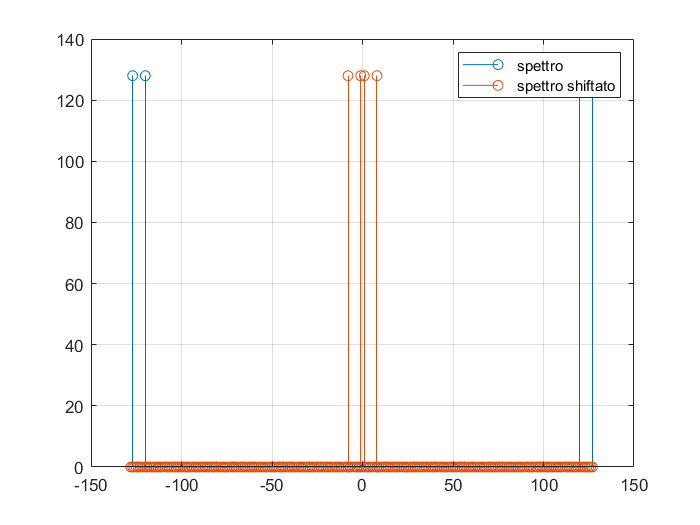

figure(4);
stem( wk, abs(X) );
hold on;
Xs = fftshift(X);
stem( wk, abs(Xs) );
grid;
legend('spettro','spettro shiftato');

posso notare che i 4 impulsi ora ricadano precisamente nelle rispettive frequenze: -1, 1 e -8, 8.

#### PARTE REALE E PARTE IMMAGINARIA

Anche se la parte informativa della DFT sta tutta nel modulo dello spettro, la DFT è comunque una sequenza di numeri complessi, pertanto, essi hanno parte reale, parte immaginaria e, quindi, anche una fase.

Ripulisco il segnale da eventuali termini che possono essere soggetti ad errori numerici così da avere una DFT "pulita" da errori numerici

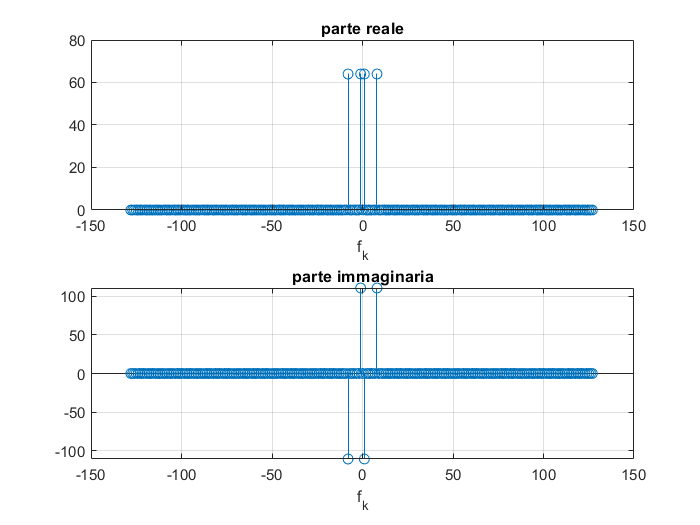

Xreal = real(Xs);
j = find( abs(Xreal) <= 10e-10 );
Xreal(j) = 0;

Ximaginary = imag(Xs);
j = find( abs(Ximaginary) <= 10e-10 );
Ximaginary(j) = 0;


figure(5);

subplot(2,1,1), stem( wk, Xreal );
title('parte reale');
xlabel('f_k');
grid;
subplot(2,1,2), stem( wk, Ximaginary );
title('parte immaginaria');
xlabel('f_k');
grid;

posso notare che la parte reale e il modulo della trasformata sono simmetrici rispetto all'origine (funzione pari), mentre la parte immaginaria e la fase sono antisimmetriche (dispari). 

#### MODULO E FASE

considero il modulo normalizzato (essendo che moltiplico per 2/N), cioè faccio in modo che dato un segnale generico f(t), il modulo |f(t)|<=1.

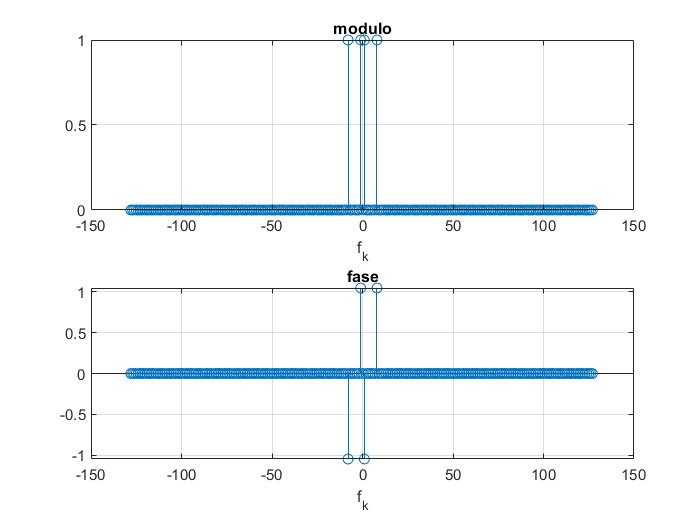

figure(6);
subplot(2,1,1), stem( wk, (2/N)*abs(complex(Xreal, Ximaginary)) );
title('modulo');
xlabel('f_k');
grid;
subplot(2,1,2), stem(wk, angle(complex(Xreal, Ximaginary)) );
title('fase');
xlabel('f_k');
grid;

infatti come già anticipato prima il modulo della trasformata è simmetrico rispetto all'origine mentre la fase è antisimmetrica.